Given the initial hidden state z0 = 0, we have the sequence:

z_{i+1} = a*z_{i} + b

a = 0.5, and the noise b randomly drawn from the Gaussian distribution (0,1)

**STEP 1: Generate 100 hidden states z's, with initial hidden state z0**

clear
clc

z0 = 0;
a = 0.5;
b = normrnd(0,1,[1,99]);
num_samples = 100;

z = zeros(1, num_samples) ;
z(1) = z0;

for i=2:num_samples
    z(i) = a*z(i-1) + b(i-1);
end


Define the observation x's give the hidden states z's, namely x_{i} is drawn from the Gaussian distribution (z_{i},1)

**STEP 2: Generate 100 observations x's, given the 100 hidden states z's**

x = zeros(1, num_samples);
for i=1:num_samples
    x(i) = normrnd(z(i), 1);
end


Given the generated x's and z's, we seek to find y's such that

y_{i} = x_{i} - ( alpha*z_{i} + beta ) 

with mean(y) = minimize \sum_{i=1}^{num_samples} ||x_{i} - ( alpha*z_{i} + beta ) || ^ 2 over alpha and beta.

**STEP 3: Find the optimal parameters alpha and beta using Least-Squares Fitting**

Z = ones(num_samples, 2);
Z(:,2) = z';
% calculate alpha, beta
ab = (Z' * Z) \ (Z' * x');

% calculate estimate x_hat = alpha*z + beta
x_hat = (Z*ab)';
least_square_error = sum((x_hat - x) .^ 2);
disp("least_square_error ")

least_square_error 


disp(least_square_error)

   81.3318



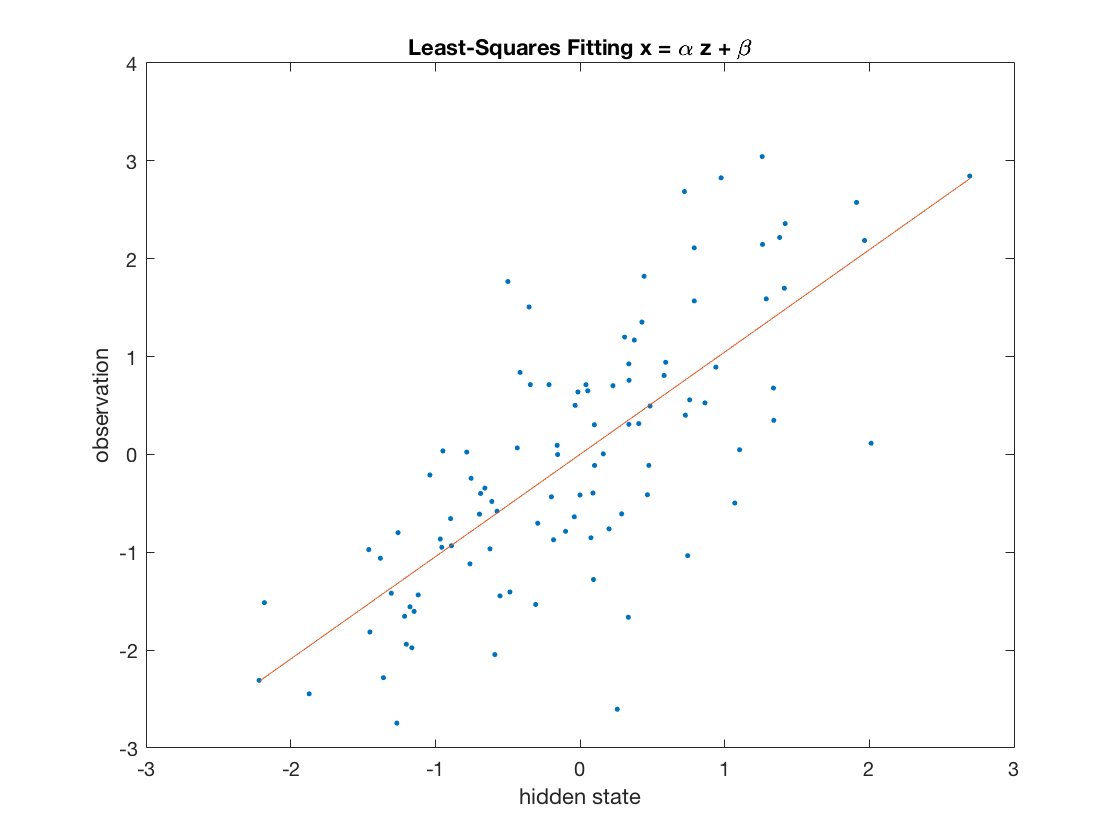

% visualize the original data 
figure(1)
plot(z, x,'.')
title("Least-Squares Fitting x = \alpha z + \beta")
xlabel('hidden state')
ylabel('observation')
hold on

% Plot the best fit line.
plot(z, x_hat)

**STEP 4: Calculate y**

y = x - x_hat;

saveas(figure(1),'sample(x,z).png')